# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 4ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

clear;clc;close all

## Άσκηση 1 : Στοχαστικές Διαδικασίες 

### Υλοποίηση Στοχαστικής Διαδικασίας

K = 100;
n = -50:200;
A = rand(K,1) - 1/2;



mask = ((n > 0) - (n - 100 > 0));


x = A* mask ;% ones(length(mask),length(mask));

mask2D = repmat(mask,K,1);

x = A .* mask2D;


mean_val = mean(x);

Acor = x'*x/K;
Sd = 20*log10(fftshift(abs(fft2(Acor))));

### Γραφικές Παραστάσεις

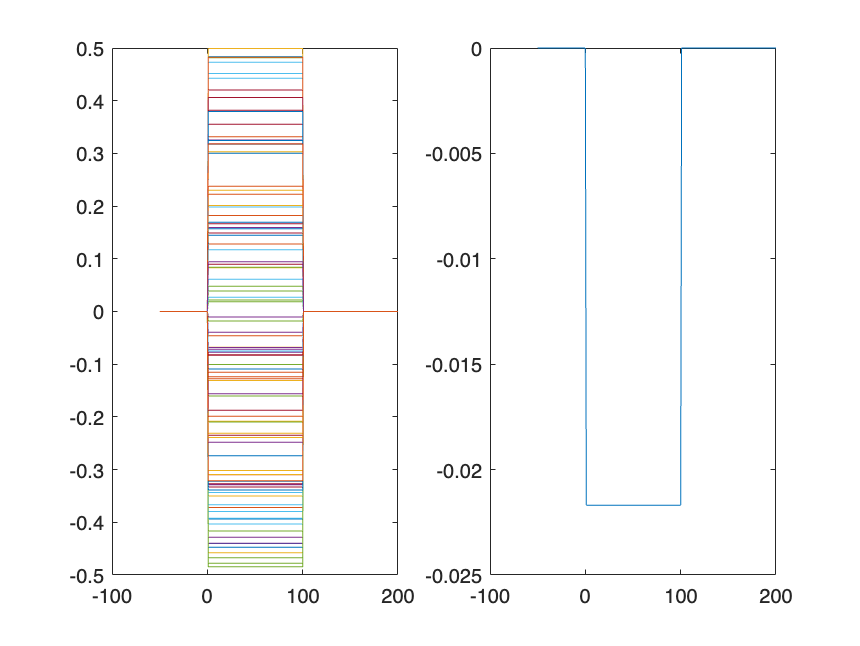

subplot(121);plot(n,x);
subplot(122);plot(n,mean_val);

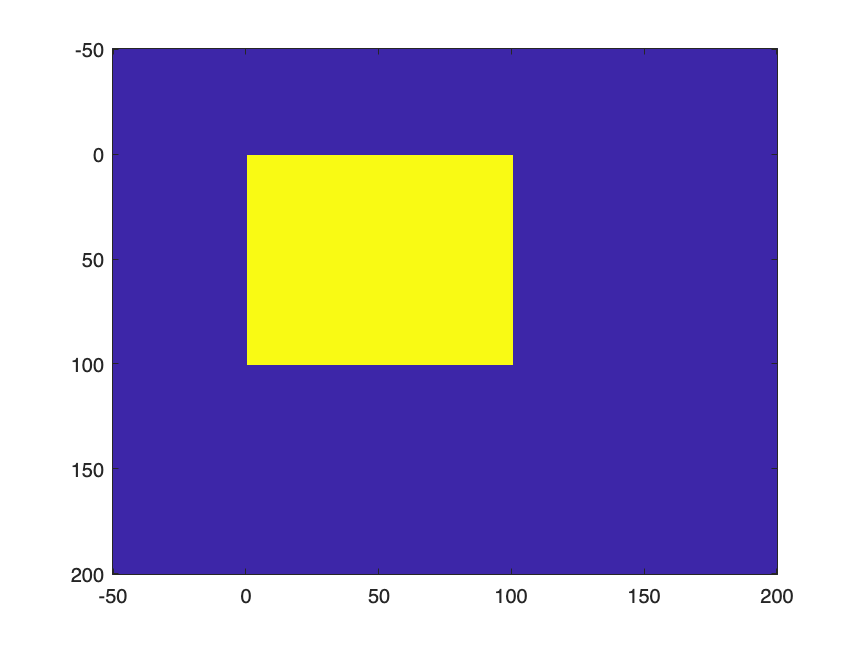


figure; imagesc(n,n,Acor)

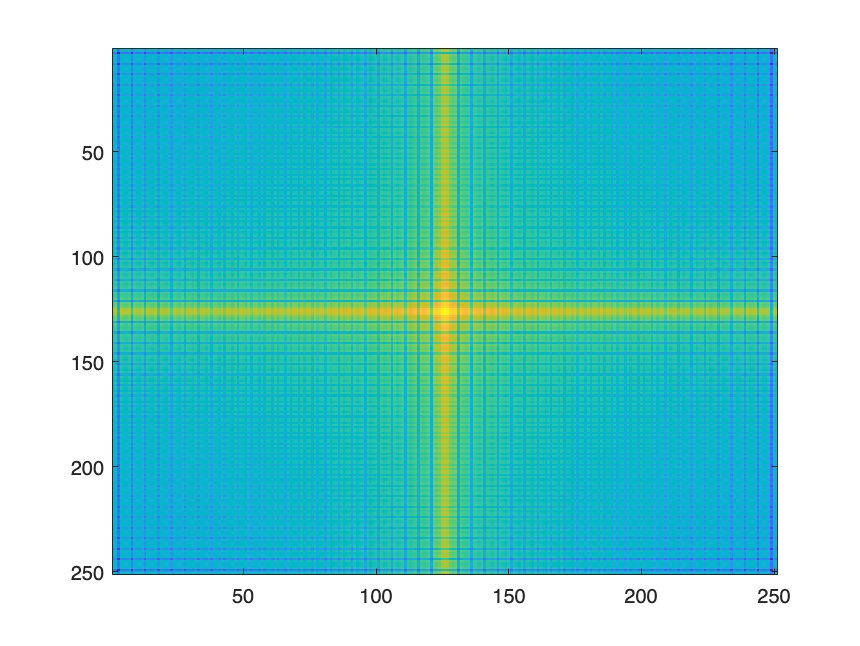


figure; imagesc(Sd)

## Άσκηση 2 : Στοχαστικές Διαδικασίες 

### Υλοποίηση Στοχαστικής Διαδικασίας

K = 100;
n = -50:200;
A = randn(K,1);



mask = ((n > 0) - (n - 100 > 0));


x = A* mask ;% ones(length(mask),length(mask));

mask2D = repmat(mask,K,1);

x = A .* mask2D;


mean_val = mean(x);

Acor = x'*x/K;
Sd = 20*log10(fftshift(abs(fft2(Acor))));

### Γραφικές Παραστάσεις

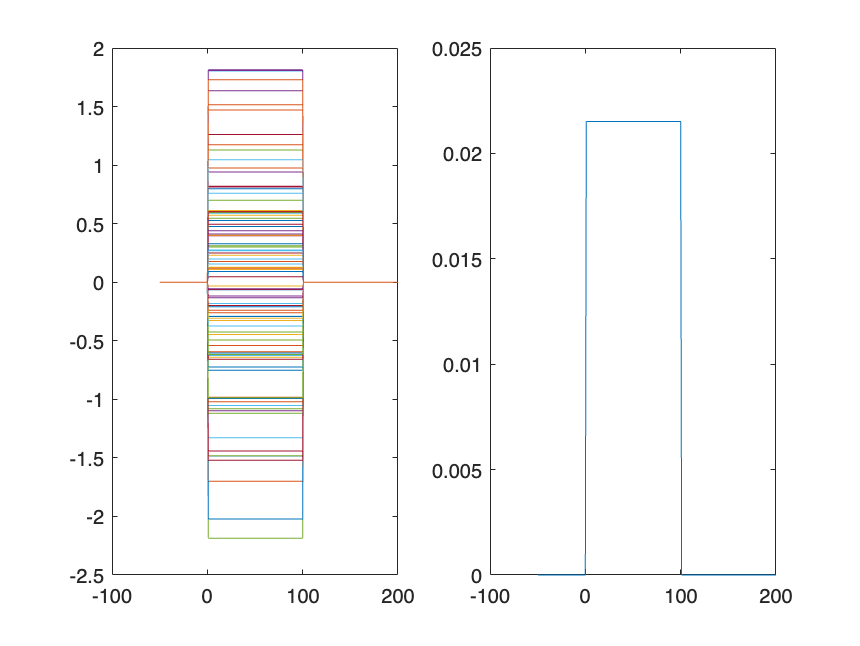

subplot(121);plot(n,x);
subplot(122);plot(n,mean_val);


figure; imagesc(n,n,Acor)

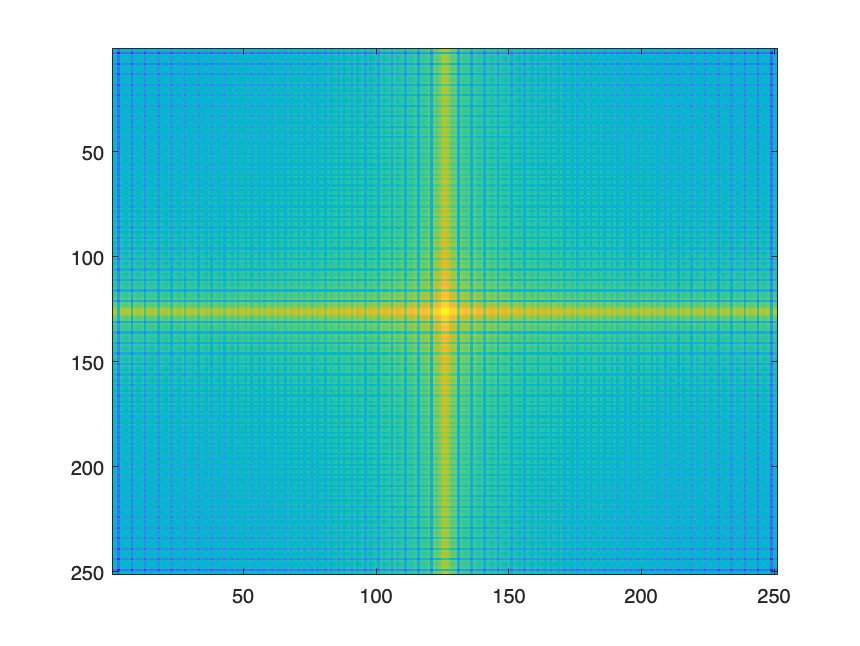


figure; imagesc(Sd)

## Άσκηση 3 : Βασικοί Νόμοι της Στατιστικής

### Φόρτωση Βίντεο και Επιλογή Πίξελ 

## Άσκηση 4 : FIR Φίλτρο Wiener

### Φόρτωση Βίντεο και Επιλογή Πίξελ 